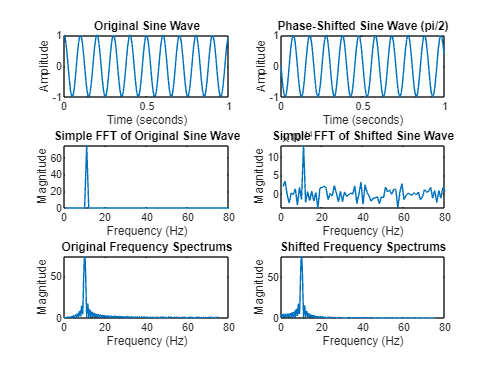

% Define sampling frequency (Fs) in Hz
Fs = 150;  % Choose a sampling frequency higher than the signal frequency

% Define frequency of the sine wave (f) in Hz
f = 10;

% Create time vector (t) for 1 second with samples based on Fs
t = 0:1/Fs:1-1/Fs;

% Generate the original sine wave signal (x)
x_original = cos(2*pi*f*t);

% Generate the phase-shifted sine wave signal (x_shifted) with pi/2 shift
x_shifted = cos(2*pi*f*t + pi/2);

% Take the FFT of the original sine wave (y_original)
y_original = fft(x_original);

y_shifted = fft(x_shifted);
% Define length of the FFT (nfft)
nfft = 1024;  % Choose an FFT length that is a power of 2 for efficiency


X = fft(x_original, nfft);

% Extract the positive frequency components and magnitude (absolute values)
X_pos = X(1:floor(nfft/2));
mag_X = abs(X_pos);


% --- Part (b): Take the FFT of phase-shifted sine wave ---
% Compute the Fast Fourier Transform (FFT) of x_shifted with padding to nfft length
X_shifted = fft(x_shifted, nfft);

% Extract the positive frequency components and magnitude (absolute values)
X_pos_shifted = X_shifted(1:floor(nfft/2));
mag_X_shifted = abs(X_pos_shifted);

% Create frequency vector (f_pos) based on Fs and nfft for positive frequencies
f_pos = linspace(0, Fs/2, (nfft/2));

% --- Plot time domain and frequency domain signals ---
figure(1);

% Plot the original sine wave signal in the time domain
subplot(3,2,1);
plot(t, x_original);
title('Original Cos Wave');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Plot the phase-shifted sine wave signal in the time domain
subplot(3,2,2);
plot(t, x_shifted);
title('Phase-Shifted Cos Wave (pi/2)');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simple FFT of the original sine wave (for reference)
subplot(3,2,3);
plot(real(y_original));
xlim([0 80])
title('Simple FFT of Original Sine Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Combine plots for positive frequencies from FFT of shifted sine wave
subplot(3,2,4);
plot(real(y_shifted));
xlim([0 80])
title('Simple FFT of Shifted Sine Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Additional subplot to compare original and shifted frequency spectrums (optional)
subplot(3,2,5);
%plot(t, x_original);
plot(f_pos, mag_X);  % Full spectrum of original sine wave
title('Original Frequency Spectrums');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Additional subplot to compare original and shifted frequency spectrums (optional)
subplot(3,2,6);
%plot(t, x_original);
plot(f_pos, mag_X_shifted);
title('Shifted Frequency Spectrums');
xlabel('Frequency (Hz)');
ylabel('Magnitude');